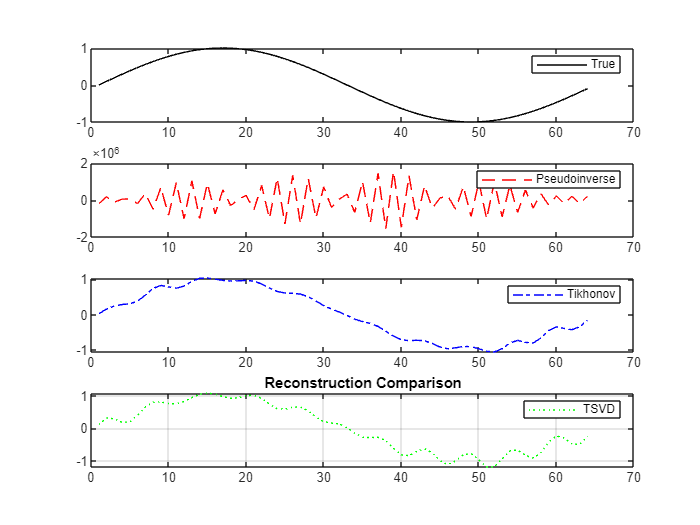

n = 64;
A = blur_operator(n, 2.0);
x_true = sin(2*pi*(0:n-1)'/n);
y = A * x_true;

% Add noise
sigma = 0.05;
[y_noisy, ~] = add_gaussian_noise(y, sigma);

% Reconstructions
x_pinv = pseudoinverse_reconstruction(A, y_noisy);
x_tikh = tikhonov_reconstruction(A, y_noisy, 0.1115);
x_tsvd = tsvd_reconstruction(A, y_noisy, 25);

figure;
subplot(4,1,1)
plot(x_true,'k');
legend("True")
subplot(4,1,2)
plot(x_pinv,'r--');
legend("Pseudoinverse")
subplot(4,1,3)
plot(x_tikh,'b-.');
legend("Tikhonov")
subplot(4,1,4)
plot(x_tsvd,'g:');
legend("TSVD")
title('Reconstruction Comparison');
grid on;

function x = pseudoinverse_reconstruction(A, y)
    x = pinv(A) * y;
end

% Filters
function filt = tikhonov_filter(s, lambda)
    filt = s ./ (s.^2 + lambda^2);
end

function filt = tsvd_filter(s, k)
    filt = zeros(size(s));
    filt(1:k) = 1 ./ s(1:k);
end

function x = tikhonov_reconstruction(A, y, lambda)
    [U, s, V] = svd(A, 'econ');
    s = diag(s);

    filt = tikhonov_filter(s, lambda);
    x = (V .* filt') * (U' * y);
end

function x = tsvd_reconstruction(A, y, k)
    [U, s, V] = svd(A, 'econ');
    s = diag(s);

    filt = tsvd_filter(s, k);
    x = (V .* filt') * (U' * y);
end

function [x, history] = nsit_reconstruction(A, y, noise_level, ...
        schedule_type, tau, max_iter)

    if nargin < 4, schedule_type = 'sqrt'; end
    if nargin < 5, tau = 1.0; end
    if nargin < 6, max_iter = 100; end

    [m, n] = size(A);
    x = zeros(n,1);

    % Initial alpha
    s = svd(A,'econ');
    alpha0 = max(s)^2;

    switch schedule_type
        case 'sqrt'
            schedule = @(k) alpha0 / sqrt(k+1);
        case 'linear'
            schedule = @(k) alpha0 / (k+1);
        case 'exp'
            schedule = @(k) alpha0 * (0.9^k);
        case 'power'
            schedule = @(k) alpha0 / (k+1)^1.5;
        otherwise
            error('Unknown schedule type');
    end

    target_residual = tau * noise_level * norm(y);
    AtA = A' * A;

    history.x = {x};
    history.residuals = [];
    history.alphas = [];
    history.stopping_iter = max_iter;

    for k = 0:max_iter-1
        alpha = schedule(k);
        r = y - A*x;
        res_norm = norm(r);

        correction = (AtA + alpha*eye(n)) \ (A' * r);
        x = x + correction;

        history.residuals(end+1) = res_norm;
        history.alphas(end+1) = alpha;
        history.x{end+1} = x;

        if res_norm <= target_residual
            history.stopping_iter = k;
            break;
        end
    end
end

function A = blur_operator(n, sigma, kernel_radius)
% BLUR_OPERATOR  Circulant Gaussian blur matrix

    if nargin < 3
        kernel_radius = 10;
    end

    ksize = 2 * kernel_radius + 1;
    k = gaussian_kernel(ksize, sigma);

    A = zeros(n, n);

    for i = 1:n
        for j = 1:n
            shift = mod(i - j, n);
            if shift < ksize
                A(i, j) = k(shift + 1);
            end
        end
    end
end

function [y_noisy, noise] = add_gaussian_noise(y, sigma, rng)
    if nargin < 3 || isempty(rng)
        noise = sigma * randn(size(y));
    else
        noise = sigma * randn(rng, size(y));
    end

    y_noisy = y + noise;
end

function k = gaussian_kernel(sz, sigma)
% GAUSSIAN_KERNEL  1D Gaussian kernel

    idx = -(floor(sz/2)) : floor(sz/2);
    k = exp(-0.5 * (idx / sigma).^2);
    k = k / sum(k);
end

fprintf('Pseudoinverse MSE: %.4e\n',mse(x_true, x_pinv));

Pseudoinverse MSE: 6.6096e+11


fprintf('Tikhonov     MSE: %.4e\n', mse(x_true, x_tikh));

Tikhonov     MSE: 4.2440e-03


fprintf('TSVD         MSE: %.4e\n', mse(x_true, x_tsvd));

TSVD         MSE: 1.5761e-02
